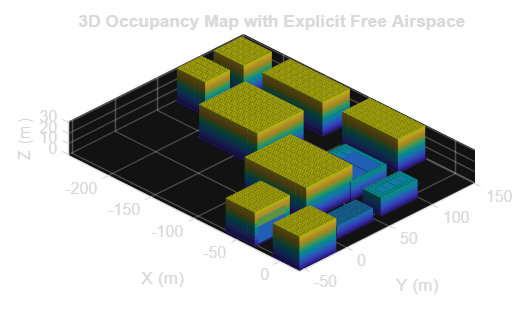

clc; clear; close all;
% Load geometry
load data/UrbanScenario.mat
% bboxes = [xmin ymin zmin xmax ymax zmax]
% Create 3D occupancy map
mapResolution = 1;     % cells per meter
occMap3D = occupancyMap3D(mapResolution);

step = 1;          
% MARK AIRSPACE AS FREE 
xmin = min(bboxes(:,1)) - 10;
xmax = max(bboxes(:,4)) + 10;
ymin = min(bboxes(:,2)) - 10;
ymax = max(bboxes(:,5)) + 10;
zmax = max(bboxes(:,6)) + 20;

xs = xmin:step:xmax;
ys = ymin:step:ymax;
zs = 0:step:zmax;

[Xf,Yf,Zf] = ndgrid(xs, ys, zs);%To Create the Lattice(1D vectors to 3D grids)
freePts = [Xf(:) Yf(:) Zf(:)];

setOccupancy(occMap3D, freePts, 0);   % FREE SPACE(a tall matrix with 3 columns(X,Y,Z)

% INSERT BUILDINGS AS OCCUPIED
for i = 1:size(bboxes,1)
    bb = bboxes(i,:);

    xs = bb(1):step:bb(4);
    ys = bb(2):step:bb(5);
    zs = bb(3):step:bb(6);

    [X,Y,Z] = ndgrid(xs, ys, zs);% Building into Points
    occPts = [X(:) Y(:) Z(:)];

    setOccupancy(occMap3D, occPts, 1);   % OCCUPIED
end

% Inflate obstacles LAST
inflate(occMap3D, 1.0);

% VISUAL CHECK
figure('Name','3D Occupancy Map (FREE + OCCUPIED)','Color','w');
show(occMap3D);
axis equal
grid on
view(45,30)
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('3D Occupancy Map with Explicit Free Airspace');


% SAVE
projectRoot = fileparts(fileparts(mfilename('fullpath')));
dataFolder = fullfile(projectRoot, "data");

if ~exist(dataFolder, "dir")
    mkdir(dataFolder);
end

save(fullfile(dataFolder, "UrbanScenario_3D.mat"), "occMap3D", "mapResolution");
